clear; close all;


## Dynamics of the Double Integrator

load("chabo_ol_dynamics_disc.mat");
% state bounds
pitch_max             = deg2rad(60);
pitch_min             = deg2rad(-60);
pitch_velocity_max    = 2*pi;
pitch_velocity_min    = -2*pi;
position_max          = 6;
position_min          = -0.25;
position_velocity_max = 2;
position_velocity_min = -2;
flywheel_velocity_max = constraints.flywheelVelocityMax;
flyhweel_velocity_min   = - constraints.flywheelVelocityMax;
constraints_scaling     = 0.75;
x_max                  = [pitch_max; pitch_velocity_max; position_max; position_velocity_max; flywheel_velocity_max] * constraints_scaling;
x_min                  = [pitch_min; pitch_velocity_min; position_min; position_velocity_min; flyhweel_velocity_min] * constraints_scaling;

% action space constraints. 75% for more conservative approach
input_scaling = 0.75;
u_max = [constraints.tiresTorqueMax; constraints.flywheelTorqueMax] * input_scaling;
u_min = [-constraints.tiresTorqueMax; -constraints.flywheelTorqueMax] * input_scaling;

## Setup Collision-Checking Functions

% Obstacles
% load('obstacle_cell_double_integrator.mat');
load("obstacle_0.75m_flipped.mat");
% State-2-Output function
x2y_function  = @(x)(x([1;3],:));
% State-in-collision function
is_state_in_collision_func = @(x)is_state_in_collision_2d_v1(x, x2y_function, obstacle_cell);
% State-connection-in-collision function
is_state_connection_in_collision_func = @(x1, x2)is_state_connection_in_collision_2d_v1(x1, x2, x2y_function, obstacle_cell);

## State Propagation Functions

% Maximum number of samples in local motion planning
Nmax        = 50;
% Sample-increment in local motion planning
N_increment = 1;
% Precompute the (pseudo-inveres of) the lifted dynamics
[Pinv_cell, D_cell] = precompute_Pinv_D(A, B, Nmax);
% Setup the LMP-function
local_motion_planning_func = @(x_initial, x_goal)local_motion_planning(x_initial, ...
                                                                       x_goal, ...
                                                                       Pinv_cell, ...
                                                                       D_cell, ...
                                                                       Nmax, ...
                                                                       u_min, ...
                                                                       u_max, N_increment);
% Single-Step propagation function
single_step_state_propagation_function = @(x, u)single_step_propagation_linear_dynamics(x, u, A, B);

## Setup Kinodynamic-RRT-Object

% Initial state
x_initial = [0; 0; 0; 0; 0];
% Setup the KD-RRT-Object
kd_rrt = CKinodynamicRRT(x_max, ...
                         x_min, ...
                         is_state_in_collision_func, ...
                         is_state_connection_in_collision_func, ...
                         x_initial, ...
                         local_motion_planning_func, ...
                         single_step_state_propagation_function);

## Kinodynamic Exploration

% Maximum number of samples
N = 20000;
% Plan
tic;
kd_rrt.feasible_kinodynamic_exploration(N);
toc;

Elapsed time is 16.251832 seconds.


## Plot the Results

figure;
% Plot the tree
kd_rrt.root_node.draw(x2y_function);
% Plot the initial configuration
l_x_initial = plot(x_initial(3), x_initial(1), 'x', 'MarkerSize', 24, 'LineWidth', 4, 'Color', '#984ea3');
% Setup the limits
xlim([x_min(3), x_max(3)]);
ylim([x_min(1), x_max(1)]);
% Labels
xlabel('first output');
ylabel('second output');
% Plot the obstacles
obstacle_cell_flipped = flip_obstacle(obstacle_cell);

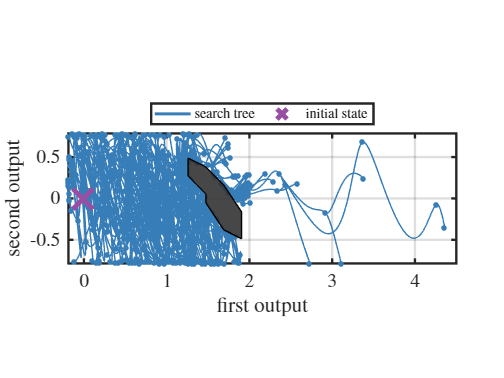

for n = 1:length(obstacle_cell_flipped)
    % Retreive obstacle
    obstacle = obstacle_cell_flipped{n,1};
    % Plot the obstacle
    plot(obstacle, 'FaceColor', 0.2*ones(1,3), 'FaceAlpha', 0.9);
end
% Legend
l_tree = plot(1, 1, '-', 'Color', '#377eb8');
legend_cell = {'search tree', 'initial state'};
legend([l_tree, l_x_initial], legend_cell, 'Location', 'northoutside', 'FontSize', 12, 'Orientation', 'horizontal', 'NumColumns', 3);
% Aspect
daspect([1,1,1]);